Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') )
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

velocita_porta = 1000000

velocita_porta = 1000000

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), velocita_porta, Timeout=1);
configureTerminator(STM32_ser,"CR");

Acquisisco il segnale:

l_singolo = 100;
n_sezioni = 10;

STM32_ser.flush;
STM32_ser.write('V','char');
V_REF = read(STM32_ser, 1, 'uint16');
V_REF

V_REF = 24344


STM32_ser.flush;
STM32_ser.write('?','char');

dati_letti = read(STM32_ser, (n_sezioni*l_singolo), 'uint16');

if(exist('vec'))
    delete('vec')
end


vec = {};

for i = 1:ceil(length(dati_letti)/l_singolo)
    divisione = dati_letti(((i-1)*l_singolo) +1 : i*l_singolo);
    ruotati = circshift(divisione(1:end-1), divisione(end)-2);

    ruotati = ruotati ./ 2^16 * 3.3;
    vec{i} = ruotati;
end

Grafico segnale

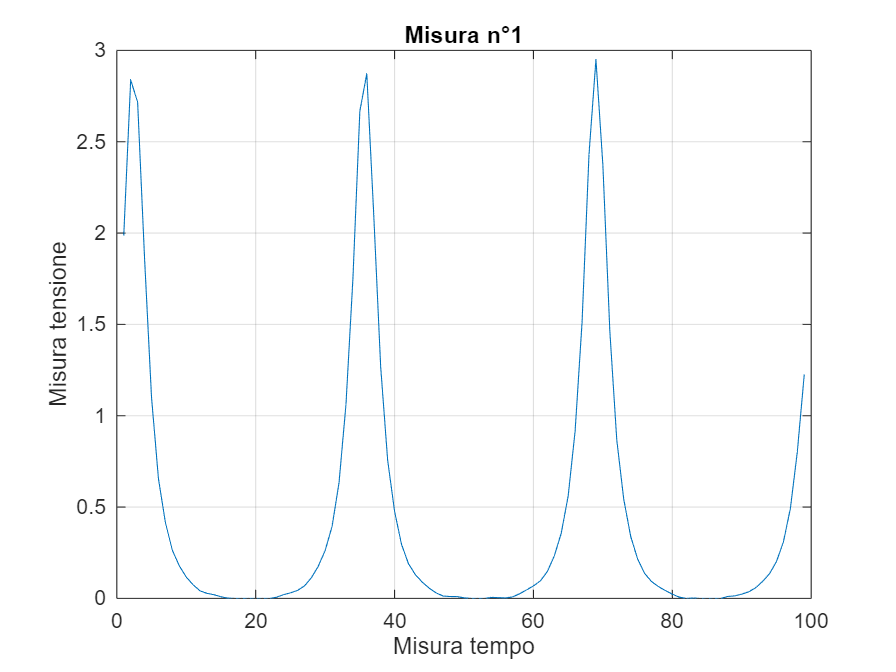

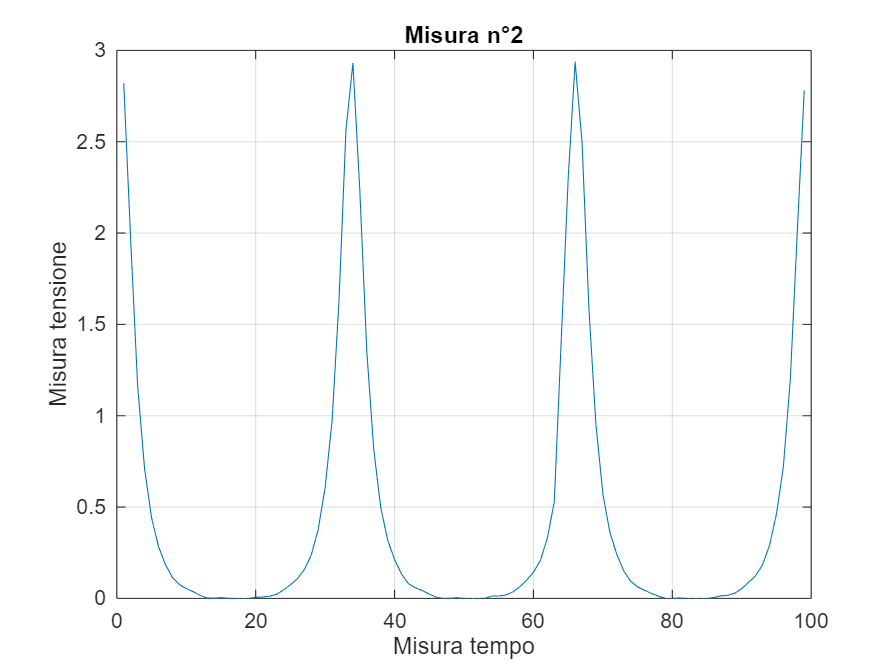

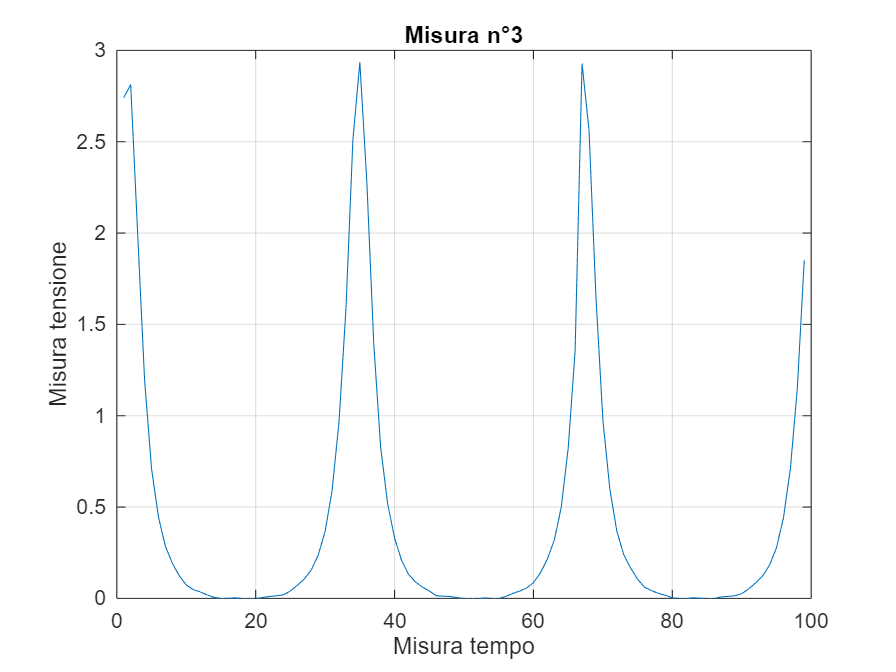

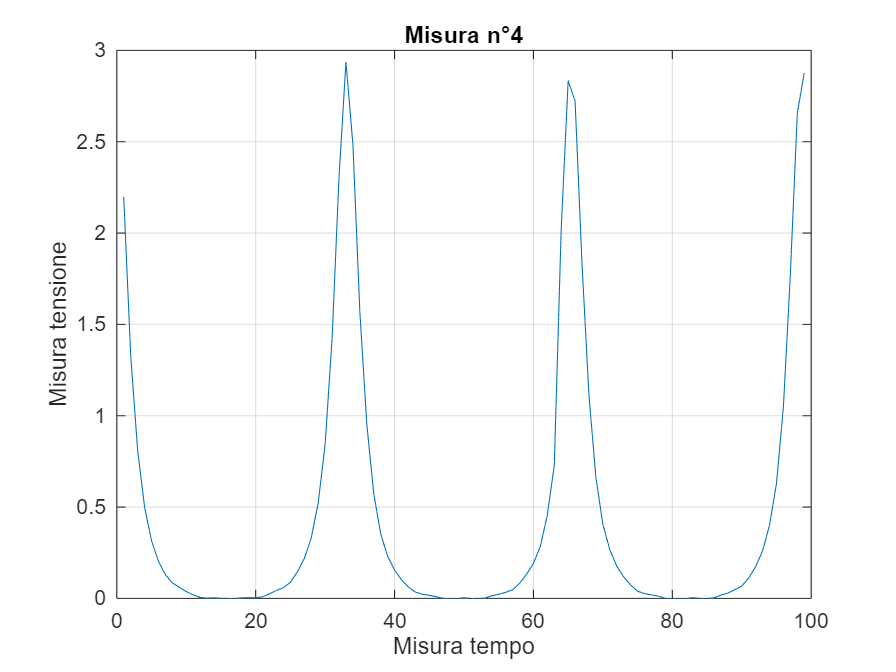

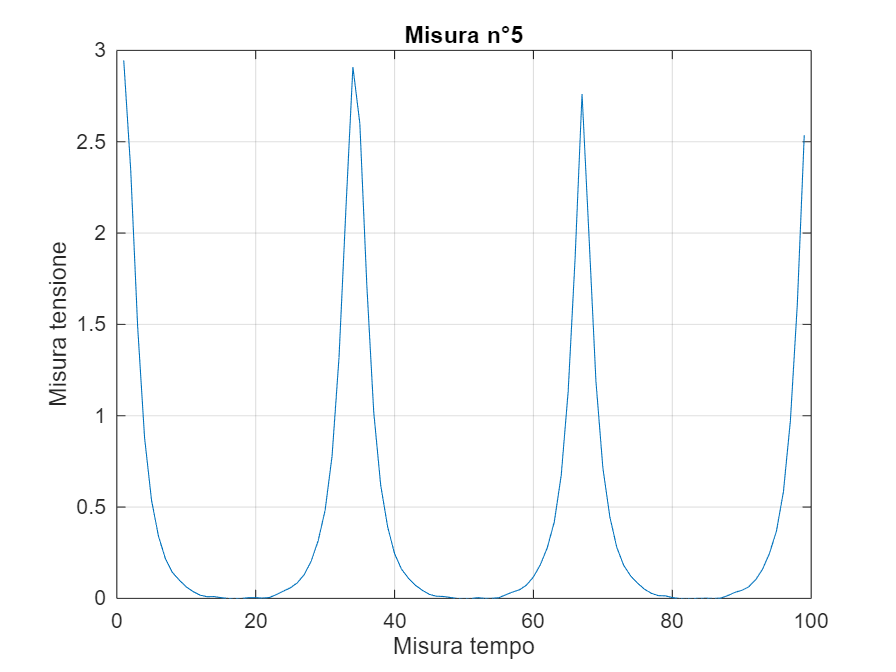

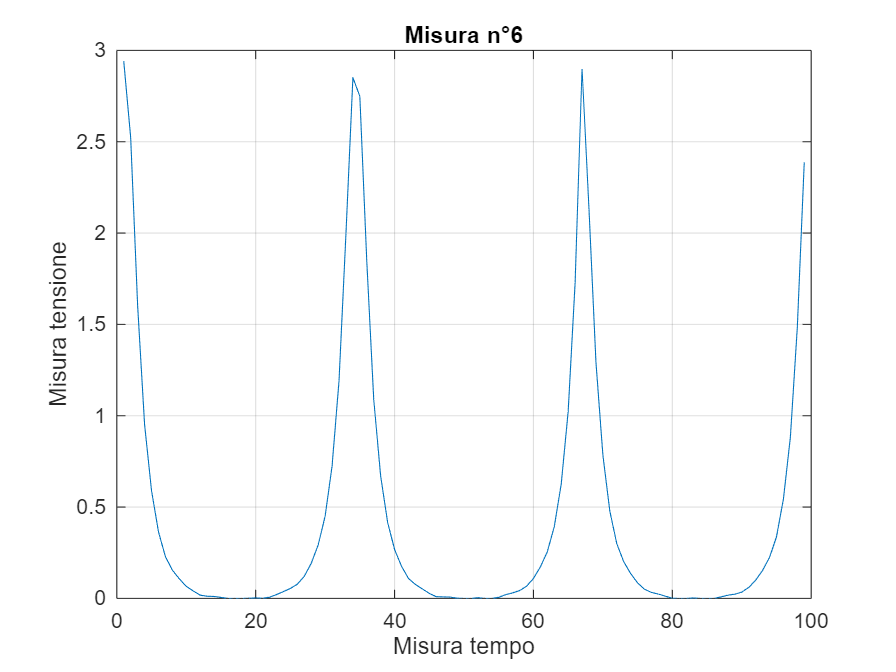

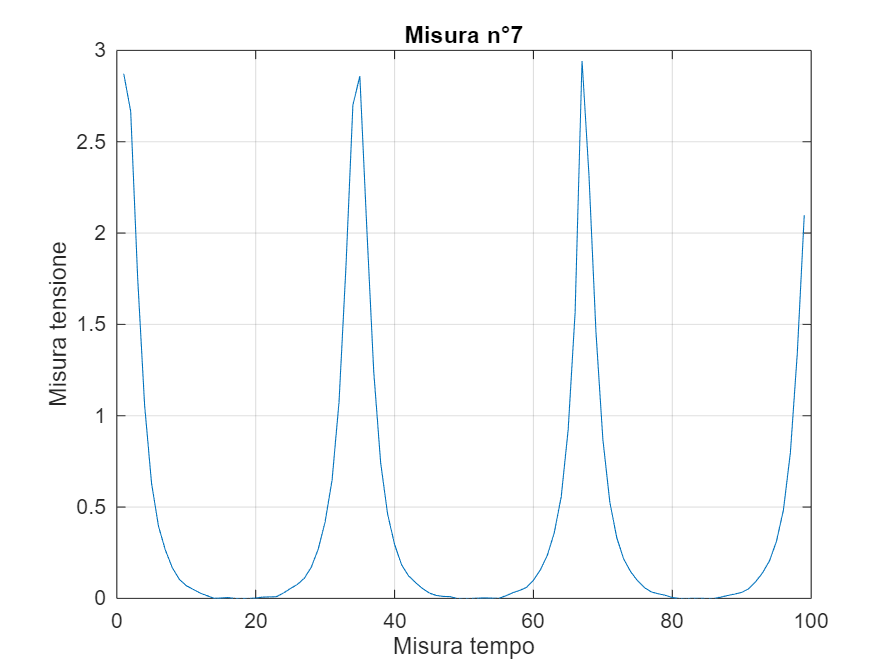

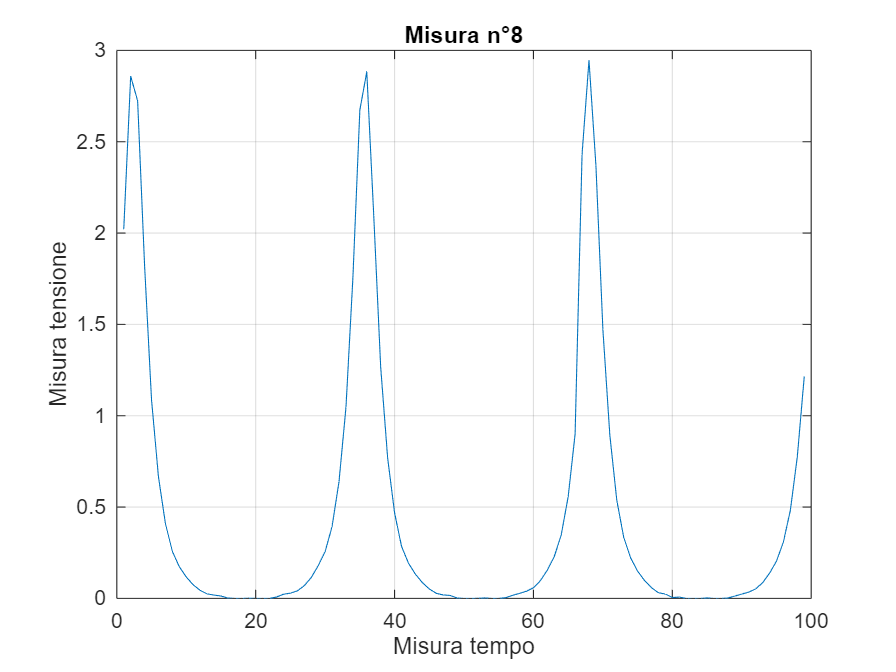

function plot_section(data_vector, index)
    if index < length(data_vector)
        plot(1:length(data_vector{index}), data_vector{index});
        title("Misura n°"+num2str(index));
        xlabel("Misura tempo")
        ylabel("Misura tensione")
        grid on
    end
end

for i=1:n_sezioni
    figure
    plot_section(vec, i);
end

% plot_section(vec, 1)
% plot_section(vec, 2)
% plot_section(vec, 3)
% plot_section(vec, 4)